# **PV**

## GLOBULOS BLANCOS

### a) Anotaciones

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_PvTk\PvTk1'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.jpg'));

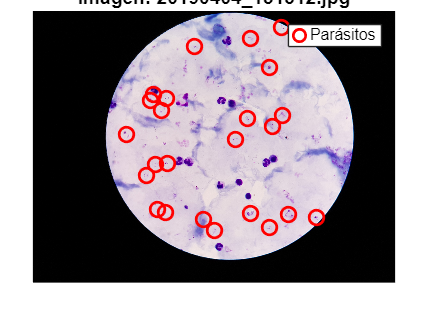

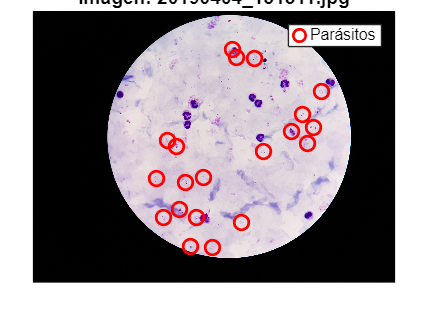

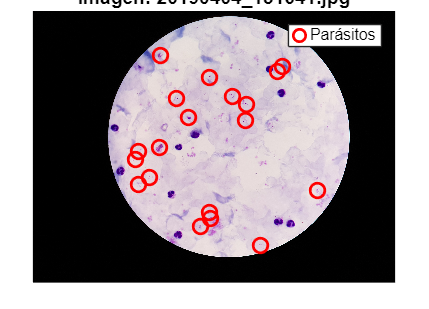

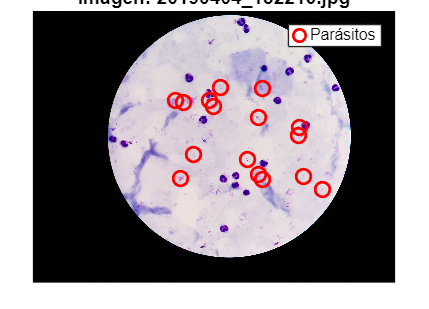

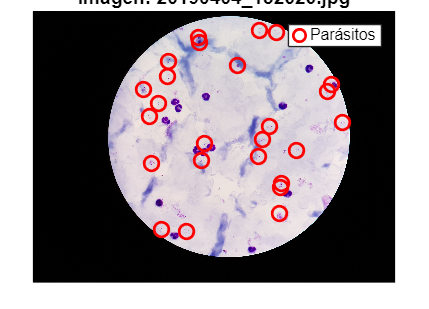

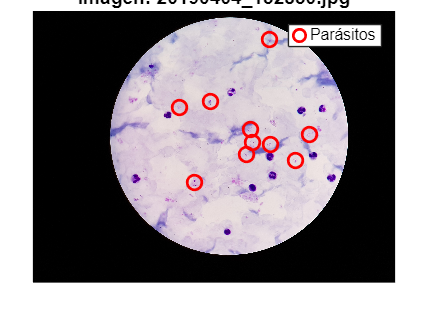

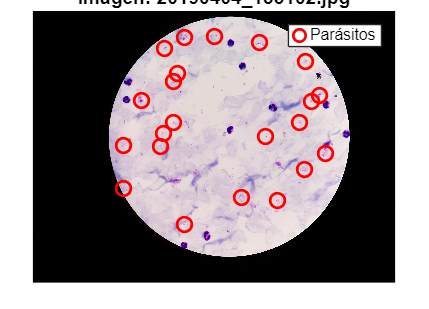

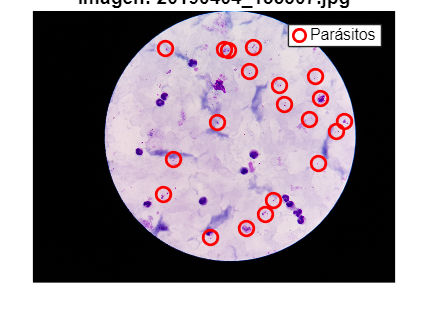

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_annotations\PvTk1', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasitized'), :);
    x_parasitos = (solo_parasitos.Var6);
    y_parasitos = (solo_parasitos.Var7);
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('Parásitos');
    hold off;
end

## PARASITOS

### b) 3º Modelo K-means color

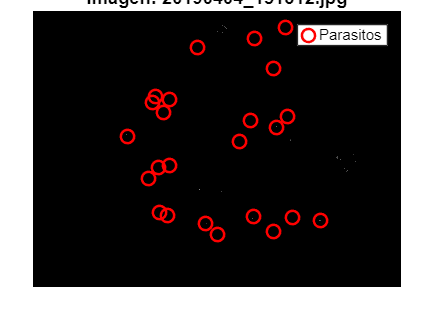

numero_de_parasitos = 24

candidatos_a_parasitos = 34

parasitos_detectados = 11

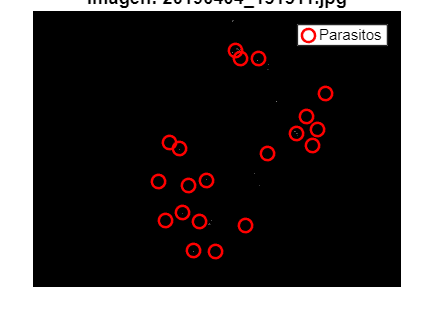

numero_de_parasitos = 20

candidatos_a_parasitos = 40

parasitos_detectados = 10

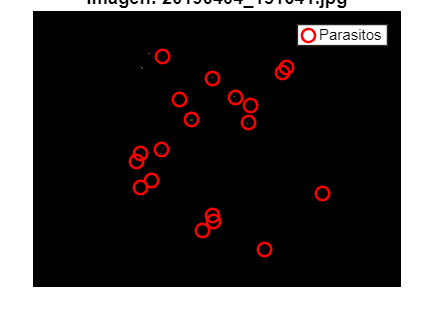

numero_de_parasitos = 19

candidatos_a_parasitos = 24

parasitos_detectados = 12

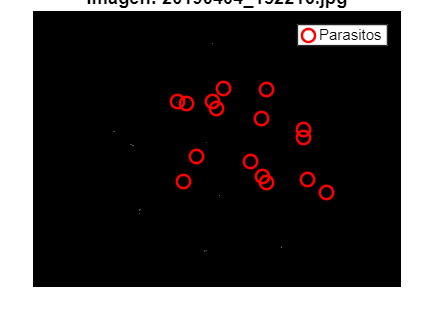

numero_de_parasitos = 16

candidatos_a_parasitos = 28

parasitos_detectados = 8

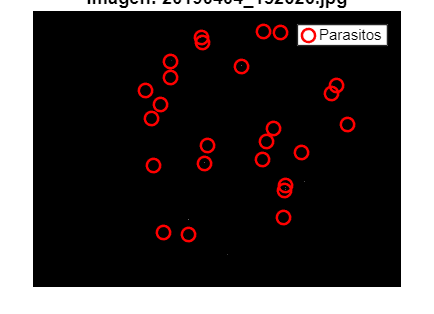

numero_de_parasitos = 25

candidatos_a_parasitos = 17

parasitos_detectados = 9

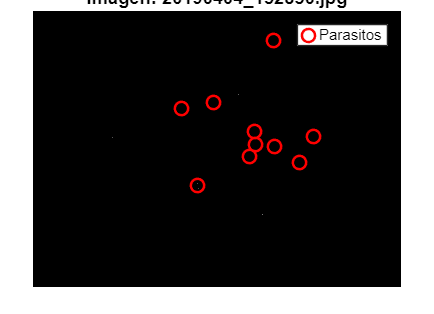

numero_de_parasitos = 10

candidatos_a_parasitos = 8

parasitos_detectados = 3

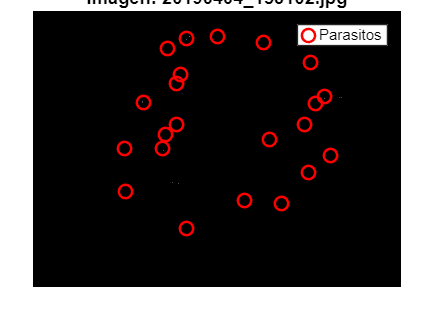

numero_de_parasitos = 22

candidatos_a_parasitos = 12

parasitos_detectados = 5

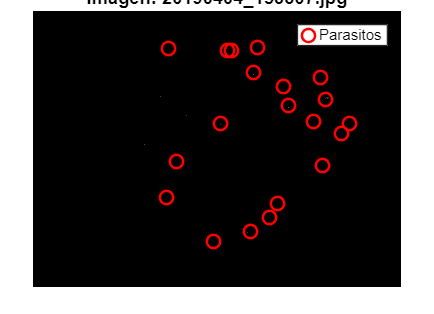

numero_de_parasitos = 20

candidatos_a_parasitos = 25

parasitos_detectados = 13

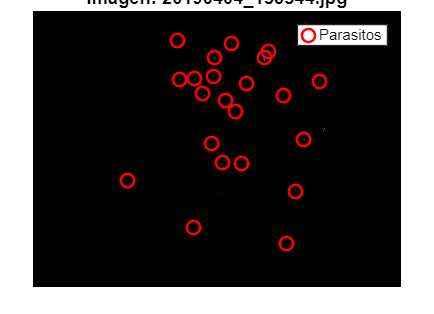

numero_de_parasitos = 22

candidatos_a_parasitos = 29

parasitos_detectados = 15

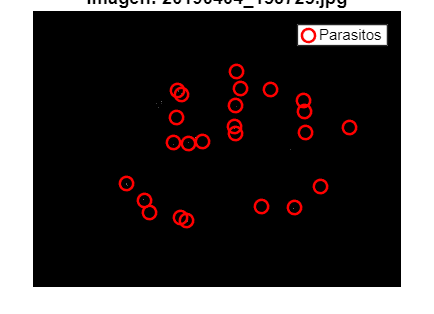

numero_de_parasitos = 24

candidatos_a_parasitos = 28

parasitos_detectados = 17

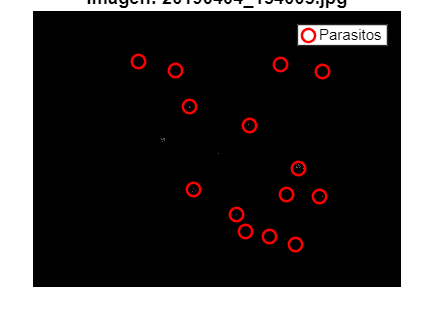

numero_de_parasitos = 14

candidatos_a_parasitos = 24

parasitos_detectados = 9

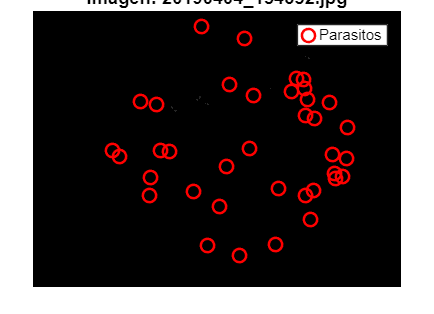

numero_de_parasitos = 37

candidatos_a_parasitos = 10

parasitos_detectados = 0

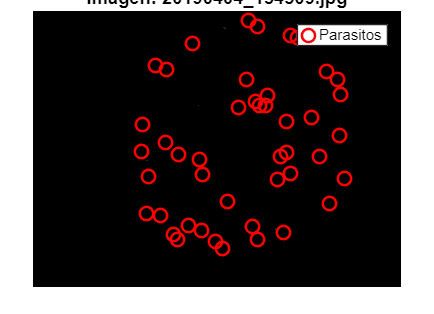

numero_de_parasitos = 45

candidatos_a_parasitos = 4

parasitos_detectados = 0

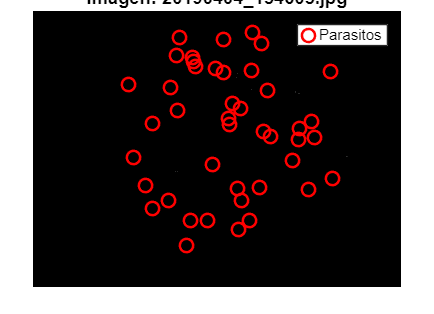

numero_de_parasitos = 43

candidatos_a_parasitos = 11

parasitos_detectados = 0

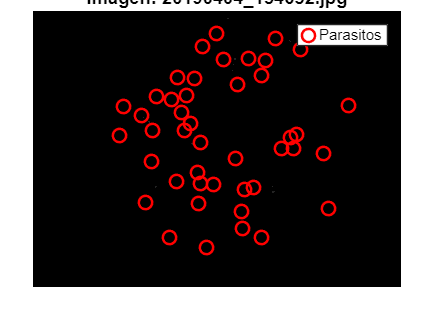

numero_de_parasitos = 44

candidatos_a_parasitos = 14

parasitos_detectados = 1

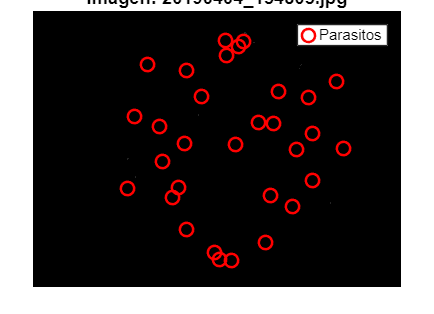

numero_de_parasitos = 31

candidatos_a_parasitos = 15

parasitos_detectados = 1

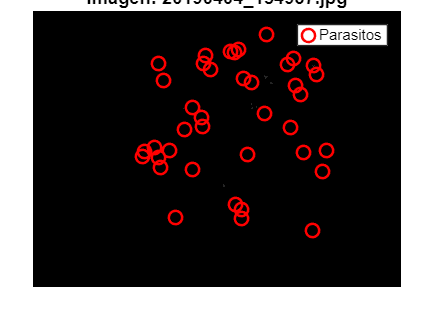

numero_de_parasitos = 39

candidatos_a_parasitos = 21

parasitos_detectados = 1

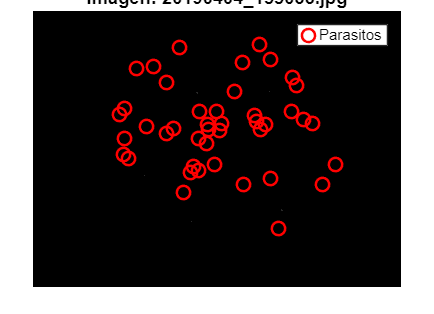

numero_de_parasitos = 43

candidatos_a_parasitos = 6

parasitos_detectados = 0

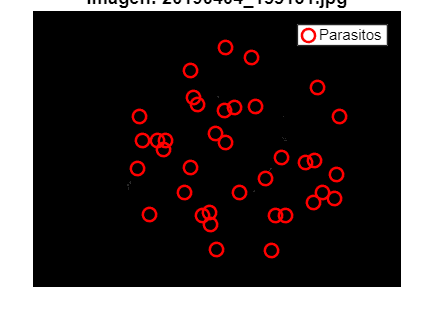

numero_de_parasitos = 37

candidatos_a_parasitos = 17

parasitos_detectados = 0

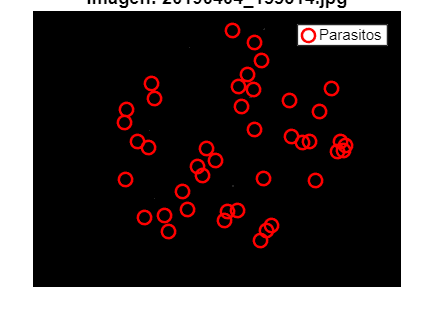

numero_de_parasitos = 42

candidatos_a_parasitos = 9

parasitos_detectados = 1

total_parasitos_reales = 0;
total_candidatos = 0;
total_parasitos_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=rgb2gray(I);
    
    % Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);

    % Aplicar imsegkmeans directamente (necesita uint8 o single)
    [L, cluster_centers] = imsegkmeans(I_sinruido, 3);

    mean_intensity = zeros(3,1);
    for c = 1:3
        mean_intensity(c) = mean(I_sinruido(L==c), 'all');
    end
    [~, idx_darkest] = min(mean_intensity);
    dark_points_mask = L == idx_darkest;
    
    % === Filtrar WBC (regiones grandes) ===
    WBC_mask = bwareaopen(dark_points_mask, 500);
    parasite_candidate_mask = dark_points_mask & ~WBC_mask;
    
    % === Procesamiento morfológico ===
    se = strel('disk', 2);
    dilated = imdilate(parasite_candidate_mask, se);
    filled = imfill(dilated, 'holes');
    opened = imopen(filled, strel('disk',1));
    
    % === Preparar imagen para imfindcircles ===
    mascara_parasitos = im2double(I_gray);
    mascara_parasitos(~opened) = 0;  % Fondo negro
    
    % % === Detección de círculos (parásitos) ===
    % [centers, radii] = imfindcircles(mascara_parasitos, [1 4], ...
    %     'ObjectPolarity','dark', 'Sensitivity', 0.93, 'EdgeThreshold', 0.1);
    % 
    % % === Mostrar resultados ===
    % figure; imshow(I); hold on;
    % viscircles(centers, radii, 'Color','r');
    
    % Visualiza la máscara final
    figure;
    imshow(mascara_parasitos);hold on;
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_annotations\PvTk1', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasitized'), :);
    x_parasitos = (solo_parasitos.Var6);
    y_parasitos = (solo_parasitos.Var7);
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
   
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('Parasitos');
    hold off;
    % ============Verificar el modelo========
    
    % Extraer el numero de parasitos
    tamano=size(solo_parasitos);
    numero_de_parasitos = tamano(1,1)

    % Candidatos a parasitos
    n=8;
    CC_2 = bwconncomp(mascara_parasitos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_parasitos=tamano(1,1)

    % Parasitos detectados
    umbral_distancia = 50;
    parasitos_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada parásito real
    for p = 1:length(x_parasitos)
        centro_real = [x_parasitos(p), y_parasitos(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                parasitos_detectados = parasitos_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un parásito detectado más de una vez
            end
        end
    end
    % Mostrar parasitos detectados
    parasitos_detectados

    % Sumas de los parasitos reales, candidatos y detectados 
    total_parasitos_reales = total_parasitos_reales + numero_de_parasitos;
    total_candidatos = total_candidatos + candidatos_a_parasitos;
    total_parasitos_detectados = total_parasitos_detectados + parasitos_detectados;
end

% Ananlizar modelo con estos resultados
total_parasitos_reales

total_parasitos_reales = 577

total_candidatos

total_candidatos = 376

total_parasitos_detectados

total_parasitos_detectados = 116


% Confusion matrix
TP=total_parasitos_detectados;
FP=total_candidatos-total_parasitos_detectados;
FN=total_parasitos_reales-total_parasitos_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 20.1040

precision=(TP/(TP+FP))*100

precision = 30.8511